clear all
clc

%% ---------------- Parameters (from tables) ----------------
% (Keep both original units and SI where convenient)
Cs10 = 1.08e-10;     % [F]  RF sheath S1 equivalent capacitance constant term
Cs20 = 3.24e-10;     % [F]  Grounded sheath S2 equivalent capacitance constant term

Ii1  = 0.0021;       % [A]  Ion current in sheath S1
Ii2  = 0.0064;       % [A]  Ion current in sheath S2

Ie10 = 0.91;         % [A]  Electron current constant term in sheath S1
Ie20 = 2.74;         % [A]  Electron current constant term in sheath S2

Rpl  = 15.51;        % [Ohm] Plasma bulk equivalent resistance
Lpl  = 2.59e-7;      % [H]   Plasma bulk equivalent inductance

% ---- Geometry / circuit / operating conditions ----
AE_cm2 = 100;        % [cm^2] Powered electrode area
AG_cm2 = 300;        % [cm^2] Ground electrode area
AE     = AE_cm2 * 1e-4;   % [m^2]
AG     = AG_cm2 * 1e-4;   % [m^2]

lbulk_cm = 5.7;      % [cm]   Plasma bulk length
lbulk    = lbulk_cm * 1e-2;  % [m]

Rrf   = 50;          % [Ohm] Equivalent source internal resistance
Rm    = 0.5;         % [Ohm] Equivalent series resistance
Rstray= 0.5;         % [Ohm] Stray parallel branch resistance
Cstray= 200e-12;     % [F]   Stray parallel branch capacitance (200 pF)

Lm2   = 1500e-9;     % [H]   Series matching inductance (1500 nH)
% Cm1   = 1550e-12;    % [F]   Shunt matching capacitance (1550 pF)
% Cm2   = 175e-12;     % [F]   Series matching capacitance (175 pF)

p_mTorr = 5;         % [mTorr] Gas pressure ~= 0.667Pa
p       = 0.667;
Tg      = 300;       % [K]     Gas temperature
Te      = 4.75;      % (as given) Electron temperature
ne      = 1.25e15;   % [m^-3]  Electron density (4.5 W)

Vrf   = 100;         % [V]   RF source voltage amplitude (25 W)
frf   = 13.56e6;     % [Hz]  RF source frequency
wrf   = 2*pi*frf;% [rad/s]


% ---- Sheath / plasma lumped parameters ----
Cm1   = 1550e-12;    % [F]   Shunt matching capacitance (1550 pF)
Cm2   = 175e-12;     % [F]   Series matching capacitance (175 pF)
par = [Cm1; Cm2; wrf];

% frf   = 13.56e6;     % [Hz]  RF source frequency
% wrf   = 2*pi*frf;% [rad/s]

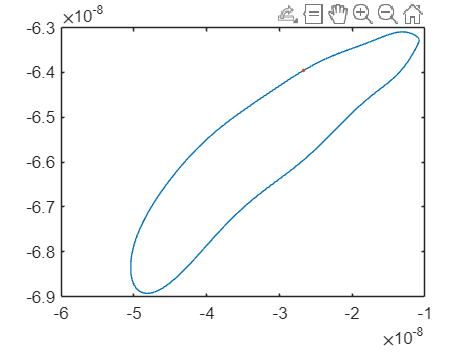

%% -------- time span --------
% tspan = [0, 0.1];   % as requested
tspan = [0, 1000*2*pi/wrf];
%% -------- initial condition (example) --------
% x = [Q_loop1; Q_loop2; Q_loop3; I_loop2; I_loop3; Q_s1; Q_s2]
x0 = zeros(7,1);
% load('x0', 'x0')


%% -------- solve --------
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

[~,x] = ode15s(@(t,x) ccp_ode_KVL(t,x,par), tspan, x0, opts);



N = 2^10;
dt  = 2*pi/wrf/N;
ccc = 2^8;

[t,x] = ode15s(@(t,x) ccp_ode_KVL(t,x,par), 0:dt:ccc*2*pi/wrf-dt, x(end,:), opts);

a=x;
bbb = 8;
Q1=a(end-2^bbb*N+1:end,1);
Q2=a(end-2^bbb*N+1:end,2);
Q3=a(end-2^bbb*N+1:end,3);
I2=a(end-2^bbb*N+1:end,4);
I3=a(end-2^bbb*N+1:end,4);
Qs1=a(end-2^bbb*N+1:end,4);
Qs2=a(end-2^bbb*N+1:end,4);

t = t(end-2^bbb*N+1:end);

figure(1)
plot(Q1,Q3);
hold on
plot(Q1(1:N:end),Q3(1:N:end),'.');

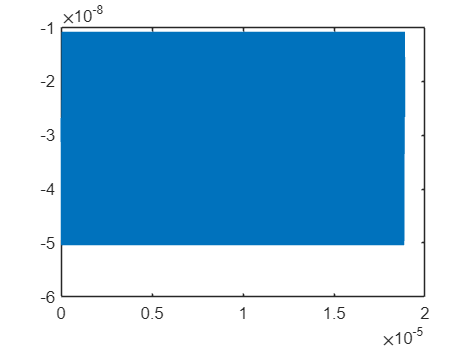




x = x(end-2^bbb*N+1:end,:);
X = fft(x)/length(Q1);
X(2:end,:)=X(2:end,:)*2;

na = length(Q1);
ff = (0:na-1)'/na*2*pi/dt;

figure(2)
plot(t,x(:,1));


figure(4)
plot(ff./wrf , log10(abs(X(:,1))));
xlim([0,15])

XH = ff(1:2^bbb:end,:)./wrf;
XA = X(1:2^bbb:end,:);



%% -------- post-process: voltages/currents --------
% Q1=x(:,1); Q2=x(:,2); Q3=x(:,3);
% I2=x(:,4); I3=x(:,5);
% Qs1=x(:,6); Qs2=x(:,7);
% 
% 

% 
% Ipl = -I3;
% IL  = I2;
% Istary = I3 - I2;
% Irf = zeros(length(I3),1);
% 
% dIpl = zeros(length(I3),1);
% for i =1:length(I3)
%     dx = ccp_ode_KVL(t(i),x(i,:)',par);
%     dIpl(i) = dx(5);
%     Irf(i)  = dx(1);
% end
% 
% Vs1  = Qs1.^2/(2*Te*Cs10^2);
% Vs2  = Qs2.^2/(2*Te*Cs20^2);
% 
% Vpl  = Lpl*dIpl - Rpl*Ipl - Vs1 + Vs2;
% 
% vsrc = Vrf * cos(wrf*t);
% 
% t_w  = t * frf;
% % t_w  = t;

## -------- plots --------

% % % trunc1 = round(length(t_w) * 0.985);
% trunc1 = 1;
% figure; hold on
% % plot(t_w, vsrc, 'b-');
% plot(t_w, Vpl,  'r-', 'LineWidth', 2);
% % xlim([t_w(trunc1), t_w(end)])
% xlabel('Phase')
% ylabel('$V_{pl}(V)$','Interpreter','latex')
% box on
% grid on
% set(gca, fontsize=16)
% 
% figure; 
% plot(t_w, Ipl, 'LineWidth', 2);
% % xlim([t_w(trunc1), t_w(end)])
% xlabel('Phase')
% ylabel('$I_{pl}(A)$','Interpreter','latex')
% box on
% grid on
% set(gca, fontsize=16)
% % 
% % trunc2 = round(length(t_w) * 0.9);
% trunc2 = 1;
% figure;
% plot(Vpl(trunc2:end), Ipl(trunc2:end), 'LineWidth', 1);
% xlabel('$V_{pl}(V)$','Interpreter','latex')
% ylabel('$I_{pl}(A)$','Interpreter','latex')
% box on
% grid on
% set(gca, fontsize=16)

% figure; hold on
% 
% % ========== 左纵坐标：绘制Vpl ==========
% yyaxis left  % 激活左纵坐标，后续绘图/标签操作针对左轴
% left_p = plot(t_w, Vpl,  'r-', 'LineWidth', 2);  % 保持原有的红色实线和线宽
% ylabel('$V_{pl}(V)$','Interpreter','latex','Color','r');  % 左轴标签（电压）
% 
% % ========== 右纵坐标：绘制Ipl ==========
% yyaxis right % 激活右纵坐标，后续绘图/标签操作针对右轴
% right_p = plot(t_w, Ipl, 'b-', 'LineWidth', 2);  % 补充蓝色实线（方便区分），保持线宽
% ylabel('$I_{pl}(A)$','Interpreter','latex','Color','b');  % 右轴标签（电流）
% 
% % ========== 统一设置公共样式 ==========
% xlim([t_w(trunc1), t_w(end)]);  % 共享x轴范围
% xlabel('Phase');               % 共享x轴标签
% box on;                        % 显示边框
% grid on;                       % 显示网格
% set(gca, 'FontSize', 16);      % 统一设置字体大小
% 
% yyaxis left
% set(gca,'YColor','r')
% yyaxis right
% set(gca,'YColor','b')